# MAT 343 Lab 5 - Your name

## Exercise 1

*NOTE: for this problem you might want to watch the second video in the tutorial videos for this lab.  Delete this note upon submission.*

*Load the file gco2.dat*

dat = load('gco2.dat');

*Create the data vectors yeat and conc and plot the data points.*

year = dat(:,1);
conc = dat(:,2);

figure
plot(year, conc, 'o', 'linewidth', 2)
xlabel('Year');
ylabel('CO2 Concentration (ppm)');
title('CO2 Data Points');
axis tight;

### (a)

*Write the code for finding and plotting the best linear fit. Make sure the vector c  is displayed.*

X_linear = [ones(size(year)), year];

z_linear = X_linear' * conc;
S_linear = X_linear' * X_linear;

U_linear = chol(S_linear);
w_linear = U_linear' \ z_linear;
c_linear = U_linear \ w_linear;

format short e;
disp('Linear Fit Coefficients:');

Linear Fit Coefficients:


disp(c_linear);

  -3.1413e+03
   1.7562e+00



hold on;
q = year;
linear_fit = c_linear(1) + c_linear(2) * q;
plot(q, linear_fit, 'k-', 'linewidth', 2);

### (b) 

*Write the code for finding the quadratic fit and plot the quadratic and linear fit in the same figure. Make sure the vector c is displayed*.

X_quad = [ones(size(year)), year, year.^2];

z_quad = X_quad' * conc;
S_quad = X_quad' * X_quad;

U_quad = chol(S_quad);
w_quad = U_quad' \ z_quad;
c_quad = U_quad \ w_quad;

disp('Quadratic Fit Coefficients:');

Quadratic Fit Coefficients:


disp(c_quad);

   5.8175e+04
  -5.9605e+01
   1.5351e-02



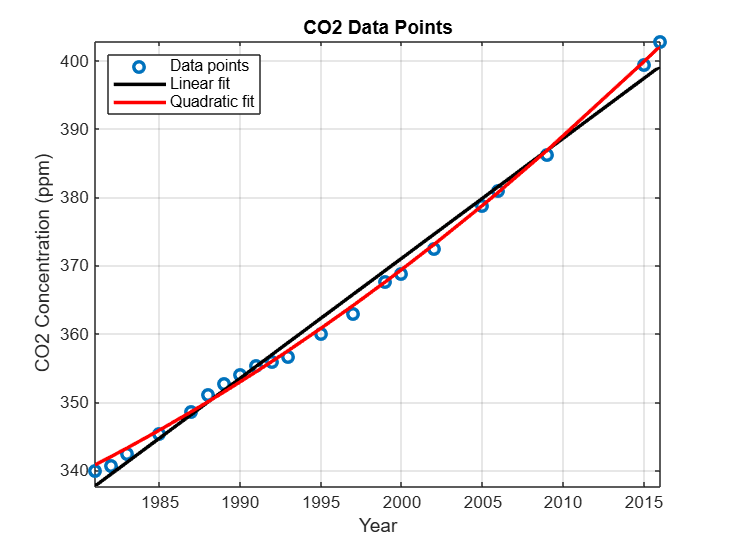

quadratic_fit = c_quad(1) + c_quad(2) * q + c_quad(3) * q.^2;
plot(q, quadratic_fit, 'r-', 'linewidth', 2);

legend('Data points', 'Linear fit', 'Quadratic fit', 'location', 'northwest');
axis tight;
grid on;

## Question 2

### (a)

*Enter the vector t (use the colon operator ":") and the vector *Y* (note the upper case) as given in the statement of the problem. Plot the data points *(t,Y),* find the best linear fit and plot it together with the points. Make sure the vector c is displayed.*

t = [0; 5; 10; 15; 20; 25];
y = [7; 7.6; 9.5; 11; 12.4; 15.3];

Y = log(y);
X = [ones(size(t)), t];

z = X' * Y;
S = X' * X;

U = chol(S);
w = U' \ z;
c = U \ w; % This is for c1, c2

disp('Linear Fit Coefficients:');

Linear Fit Coefficients:


disp(c); % Note that c(1) = c1 (ln(a)), c(2) = c2 (b)

   1.9168e+00
   3.1571e-02



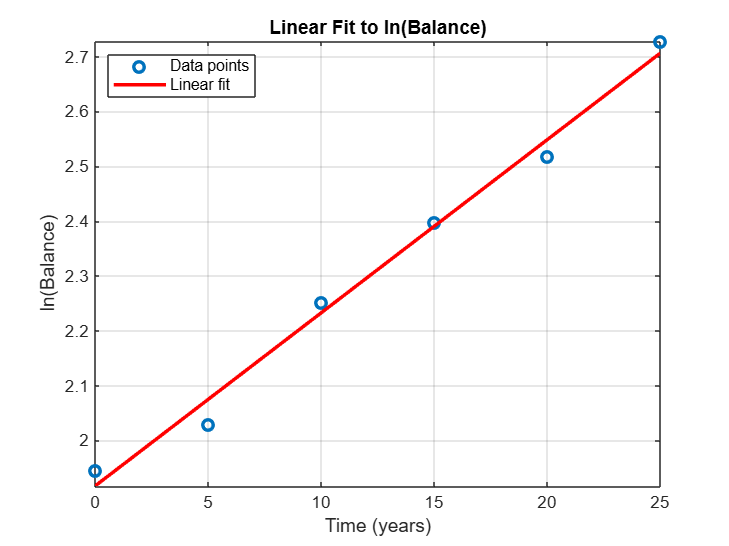

figure;
plot(t, Y, 'o', 'linewidth', 2);
hold on;
q = t;
linear_fit = c(1) + c(2) * q;
plot(q, linear_fit, 'r-', 'linewidth', 2);
xlabel('Time (years)');
ylabel('ln(Balance)');
title('Linear Fit to ln(Balance)');
legend('Data points', 'Linear fit', 'location', 'northwest');
grid on;
axis tight;

### (b)

Define  y (lower case) in terms of Y (upper case), and  $a$ and $b$ in terms of `c(1)` and `c(2) `where `c `is the vector from part (a)

a = exp(c(1));
b = c(2);

disp('Exponential Fit Parameters:');

Exponential Fit Parameters:


disp(['a = ', num2str(a)]);

a = 6.7993


disp(['b = ', num2str(b)]);

b = 0.031571


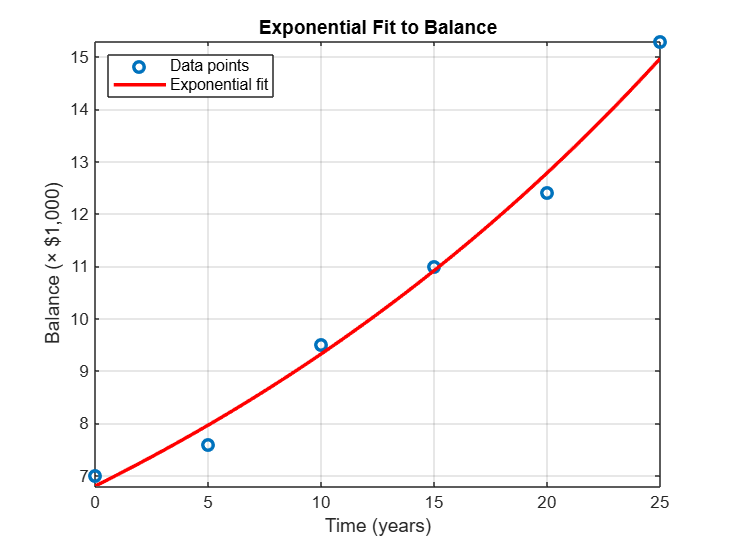

figure;
plot(t, y, 'o', 'linewidth', 2);

q = linspace(min(t), max(t), 100);
exponential_fit = a * exp(b * q);

hold on;
plot(q, exponential_fit, 'r-', 'linewidth', 2); % Exp fit
xlabel('Time (years)');
ylabel('Balance (× $1,000)');
title('Exponential Fit to Balance');
legend('Data points', 'Exponential fit', 'location', 'northwest');
grid on;
axis tight;

plot the data points (t,y) together with the exponential fit $y=ae^{bt}$. Use an appropriate vector q to graph the exponential fit.

a = exp(c(1));
b = c(2);

disp('Exponential Fit Parameters:');

Exponential Fit Parameters:


disp(['a = ', num2str(a)]);

a = 6.7993


disp(['b = ', num2str(b)]);

b = 0.031571


figure;
plot(t, y, 'o', 'linewidth', 2);

q = linspace(min(t), max(t), 100);
exponential_fit = a * exp(b * q);

hold on;
plot(q, exponential_fit, 'r-', 'linewidth', 2); % Exp fit
xlabel('Time (years)');
ylabel('Balance (× $1,000)');
title('Exponential Fit to Balance');
legend('Data points', 'Exponential fit', 'location', 'northwest');
grid on;
axis tight;

### (c)

Enter the time at which the balance will reach the given amount (make sure you explain how you find the value of t): `34.1737 years`

`y = a*e^(bt)`

`20 = a*e^(bt)`

`ln(20) = ln(a) + bt`

`t= (ln(29)-ln(a)) / b`

% We will compute the time by MATLAB coding
target_balance = 20;
t_target = (log(target_balance) - log(a)) / b;

disp(['Time to reach $20,000: ', num2str(t_target), ' years']);

Time to reach $20,000: 34.1737 years


## Question 3

Enter the vector m (use the colon operator :), and enter the average temperature Y. Both vectors must be **column** vectors.

% Define the data
m = (1:12)'; % Months (column vector)
Y = [4.9; 5.5; 6.5; 7.1; 7; 6.8; 6.2; 6; 6.4; 6; 5.3; 4.8]; % Solar radiation (column vector)

### (a)

% Build the matrix X for the degree-4 polynomial
X = [ones(size(m)), m, m.^2, m.^3, m.^4];

% Solve the normal equations
z = X' * Y; % Right-hand side
S = X' * X; % Left-hand side
U = chol(S); % Cholesky decomposition
w = U' \ z; % Solve U^T w = z
c = U \ w; % Solve U c = w

% Display the coefficients
disp('Polynomial Fit Coefficients (Part a):');

Polynomial Fit Coefficients (Part a):


disp(c);

   2.7336e+00
   2.4331e+00
  -5.0543e-01
   4.3686e-02
  -1.4387e-03



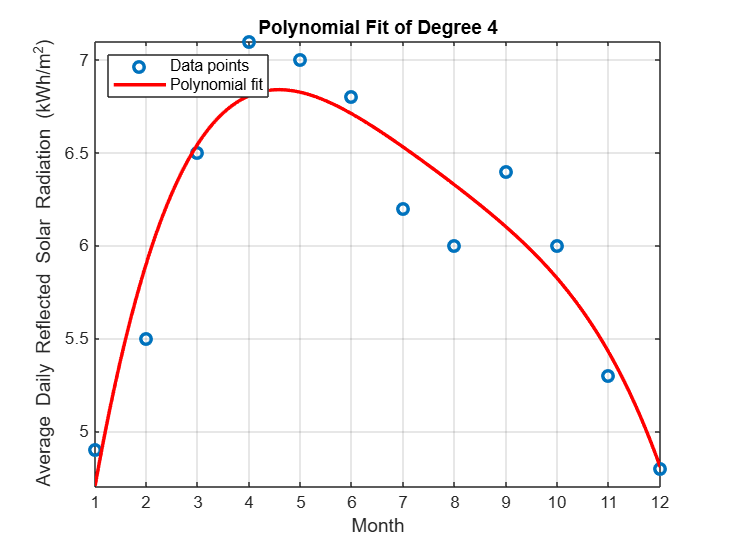


% Define a smooth vector q for plotting
q = 1:0.1:12; % Covers the range of m from 1 to 12
polynomial_fit = c(1) + c(2)*q + c(3)*q.^2 + c(4)*q.^3 + c(5)*q.^4;

% Plot the data and the polynomial fit
figure;
plot(m, Y, 'o', 'linewidth', 2); % Data points
hold on;
plot(q, polynomial_fit, 'r-', 'linewidth', 2); % Polynomial fit
xlabel('Month');
ylabel('Average Daily Reflected Solar Radiation (kWh/m^2)');
title('Polynomial Fit of Degree 4');
legend('Data points', 'Polynomial fit', 'location', 'northwest');
grid on;
axis tight;

### (b)

Enter the given commands 

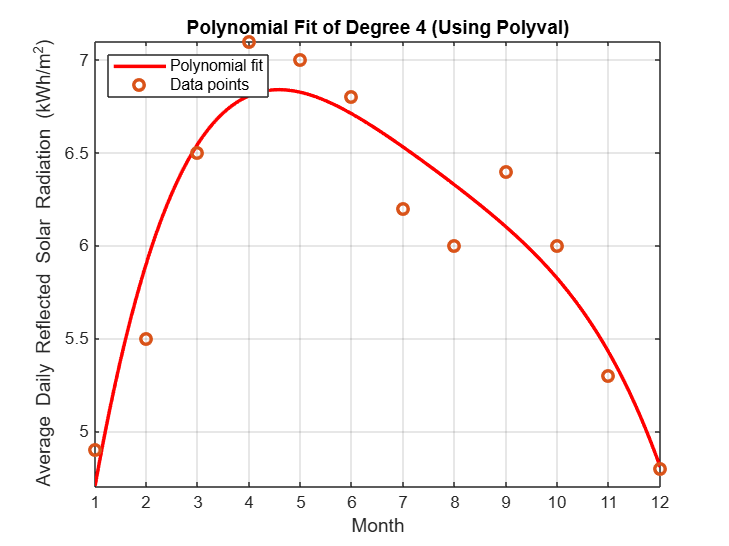

% Solve for coefficients using the backslash operator
c_b = X \ Y;

% Rearrange the coefficients for use with polyval
c_b = c_b([5:-1:1]); % Reverse the order of coefficients

% Evaluate the polynomial using polyval
z = polyval(c_b, q);

% Plot the polynomial using polyval
figure;
plot(q, z, 'r-', m, Y, 'o', 'linewidth', 2); % Polynomial fit and data points
xlabel('Month');
ylabel('Average Daily Reflected Solar Radiation (kWh/m^2)');
title('Polynomial Fit of Degree 4 (Using Polyval)');
legend('Polynomial fit', 'Data points', 'location', 'northwest');
grid on;
axis tight;


% Compare coefficients
disp('Polynomial Fit Coefficients (Part b):');

Polynomial Fit Coefficients (Part b):


disp(c_b);

  -1.4387e-03
   4.3686e-02
  -5.0543e-01
   2.4331e+00
   2.7336e+00



How do the values of c compare to the ones you found in part (a)?

Answer: The values of `c` found in Part (b) are **identical** to those found in Part (a). This is because the backslash operator `\` solves the same least-squares problem as solving the normal equations with Cholesky decomposition. Thus, the coefficients match exactly.

How does the plot compare to the one you found in part (a)?

Answer: The plot in Part (b) is **identical** to the one in Part (a). The polynomial fit remains the same since the coefficients and the evaluation of the polynomial are identical. The only difference is the method used to compute the coefficients: Part (a) uses the normal equations explicitly, while Part (b) uses MATLAB's built-in least-squares solver.